# Séance 2 : Comparaison de régulateur continu et discret 

Cette séance à pour but de comparer deux types de synthèse de régulateur discret. La première méthode étudiée consiste à synthétiser un régulateur continu pour ensuite le discrètiser et la seconde méthode consiste à discrètiser le système à réguler dans un premier temps pour ensuite synthétiser un régulateur sur base de ce système discret

Soit le système H(s)


$$\frac{7\text{ }\left(s+1\right)}{s\left(3s+1\right)}$$


H = tf([7 7],[3 1 0]);

## Synthèse d'un régulateur continu avant discrètisation

Dans cette section, c'est la première méthode qui est suivie. 

L'objectif est de créer un régulateur continu pour qu'en boucle fermée ce dernier respecte les conditions suivantes :

- pas de dépassement 

- un temps de réponse de 5 à 95% (3T)

Nous avons alors conçu un régulateur de compensation en simplifiant pôle et zéros tout en conservant l'intégrateur 

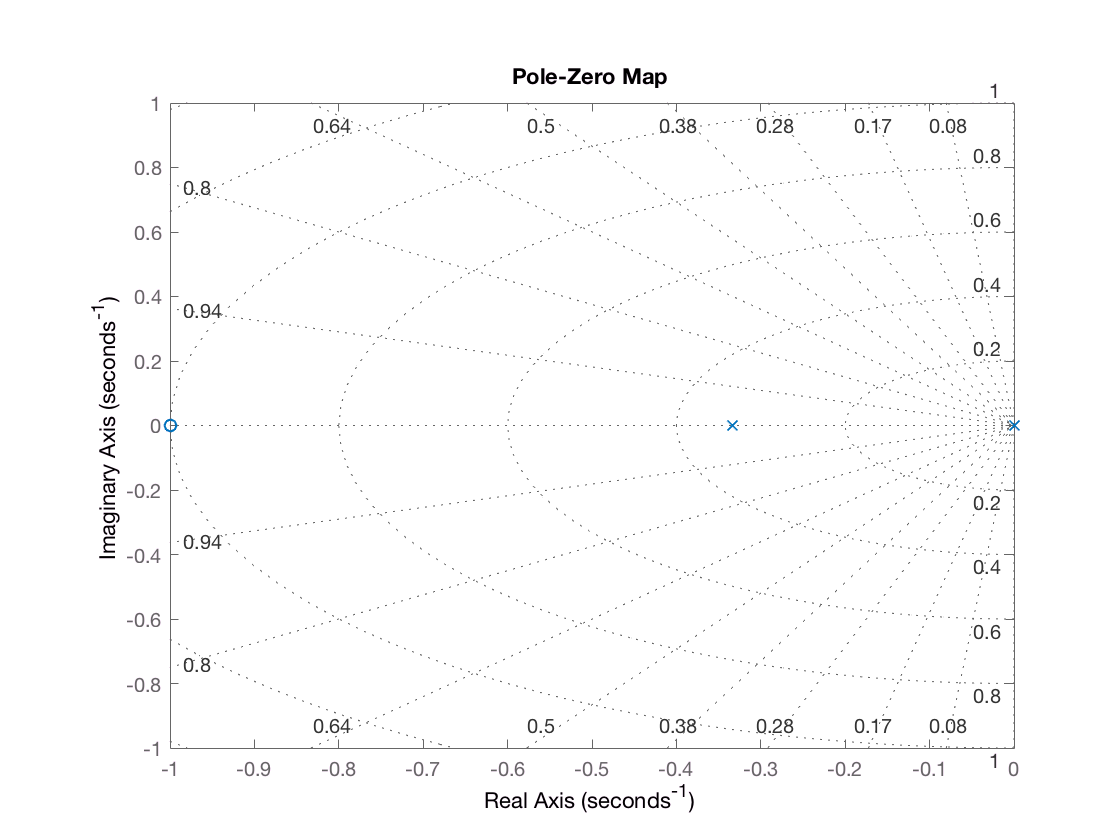

pzmap(H)
grid

Le régulateur va simplifier le **pôle en 0.33 **ainsi que le zéro en -1. Le gain d'**Evans (kc) **sera alors de 2.33 avant correction

[Zc, Pc, kc] = zpkdata(H, 'v');
R = zpk(Pc(2), Zc, 1/kc);

En effet, le gain du régulateur doit être modifié pour respecter la condition dépassement (3T = 5), le gain de correction est égal à 

K = (5/3)^(-1);

L'équation du régulateur continu peut alors être calculée ainsi que la réponse en boucle ouverte et en boucle fermée du système 

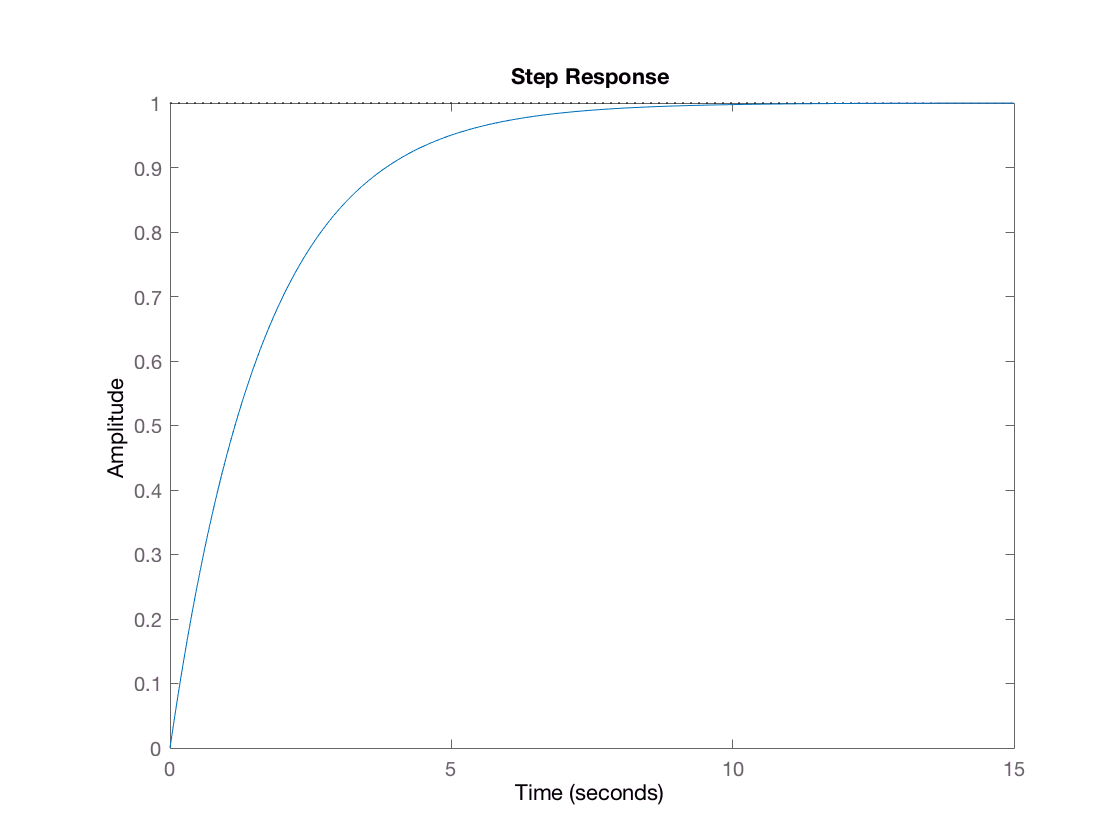

R = K*R; % compensation de R grâce au gain calculé. Ainsi nous obtenons le dépassement demandé.

Bo = R*H;

Bf = Bo /(1 + Bo);
Bf = minreal(Bf);

step(Bf)

Nous pouvons dès lors discrètiser ce régulateur par les **différences finies à gauche **avec 4 périodes d'échantillonnage différentes (h). Pour cela nous créons une matrice "h" reprenant les 4 périodes d'échantillonages désirées. Nous avons volontairement ajouter le pas "1" afin de pouvoir comparer les deux méthodes avec le même pas.

Nous alons ensuite utiliser l'outils c2d pour passer du domaines continu au domaine discret.

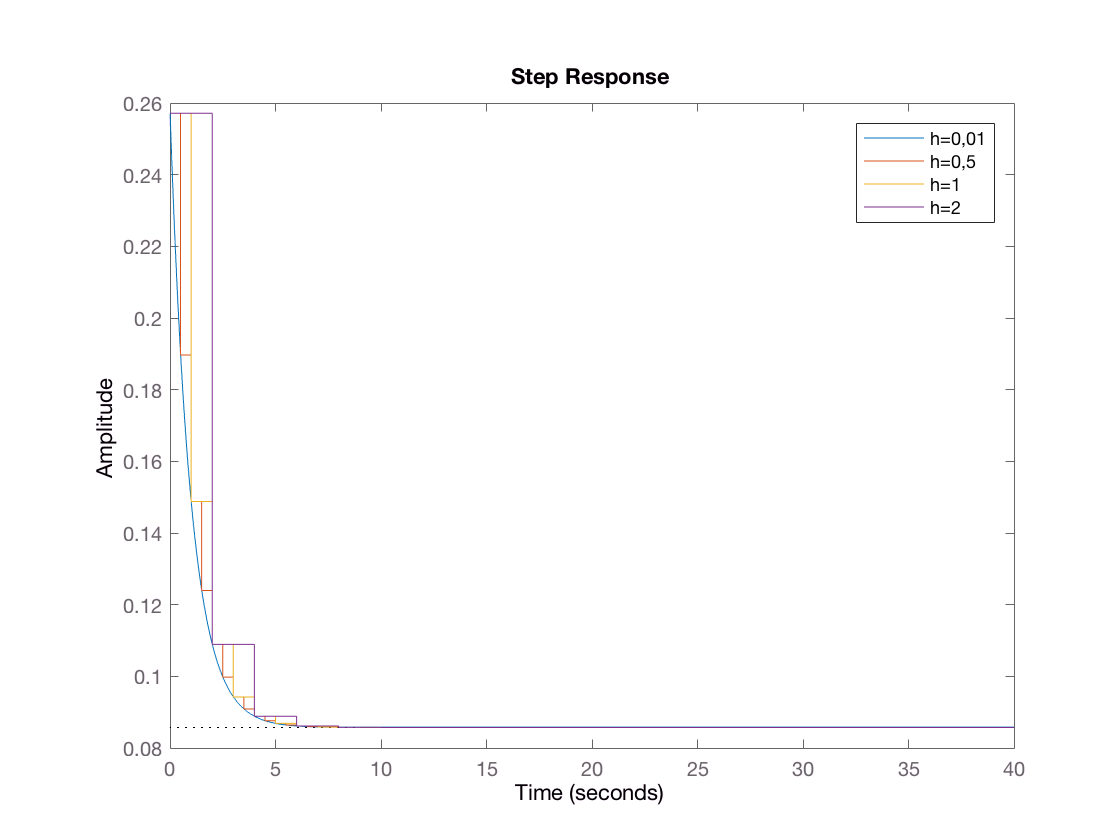

h = [0.01 0.5 1 2];
Rd1 = c2d(R, h(1)); 
Rd2 = c2d(R, h(2));
Rd3 = c2d(R, h(3));
Rd4 = c2d(R, h(4));

stepplot(Rd1, Rd2, Rd3, Rd4);
legend('h=0,01', 'h=0,5', 'h=1', 'h=2');

Observons que dans chacune des méthodes, nous sommes bien sur la courbe à chaque instant d'échantillonnage. Bien que d'un point de vue temporel la discrétisation du régulateur ne correspond pas en dehors de ces moments, commes nous ne nous intéressons qu'à la valeur aux momeents de la prise de l'échantillon, nous jugeons que la discrétisation est fidèle au système original.

## Synthèse d'un régulateur sur base d'un système discrètisé

Cette section étudie la deuxième méthode de synthèse de régulateur discret. Comme énoncé dans l'introduction, le régulateur discret de compensation est synthétiser sur base du système discrétisé. La transmittance discrète du système est alors obtenue par la méthode de l'équivalent échantilloné bloqué avec h = 1.

Hd = c2d(H,1); 
Rd = c2d(R, 1);

Suivant la même démarche que lors de la synthèse du régulateur continu, nous pouvons déterminer l'équation du régulateur discret sur base de la transmittance discrète du système.

[Zd, Pd, kd] = zpkdata(Hd, 'v');

Nous allons ensuite déterminer le gain nécessaire au déplacement de notre pôle en -3/5. 

kch = 1 - exp((-3/5)*1);

En multipliant ensuite le régulateur obtenu grâce aux pôles, zéros et gain du système par le gain de compensation calculé, nous obtenons le régulateur discret supposé identique à celui de la section précédente.

Rd = kch * zpk(Pd(2), Zd, 1/kd, 1);

Nous calculons ensuite les transmittances en boucle ouverte et fermée.

Bod = minreal(Hd*Rd);
Bfd = minreal (Bod/(1+Bod));


En comparant le regulataurs obtenus dans la section précédante à celui obtenu par synthèse d'un système discret, nous obtenons les graphes suivants. 

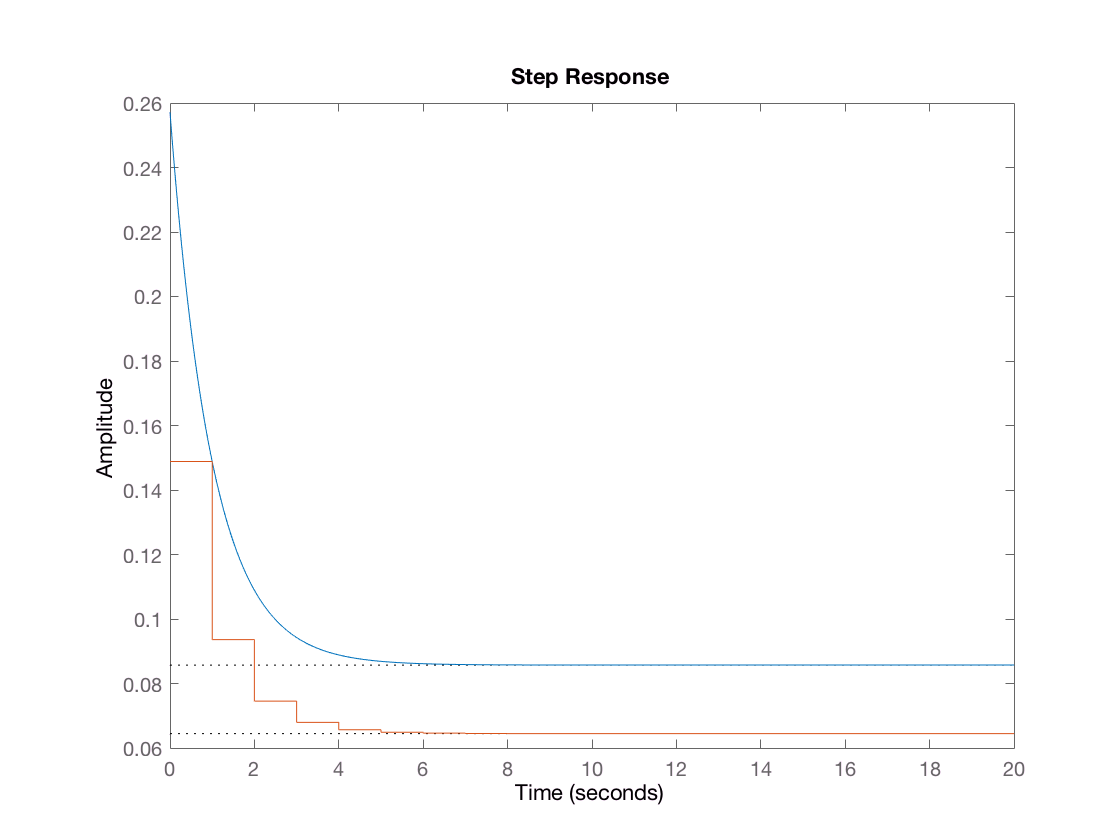

stepplot(R, Rd);

Remarquons tout d'abord que le deux régulateurs diffèrent! En effet un écart significatif apparait entre les deux dès le deuxième instant d'échantillonnage.

En comparant les transmittances obtenues dans la section précédante à celles obtenues par synthèse d'un système discret, nous obtenons les graphes suivants. 

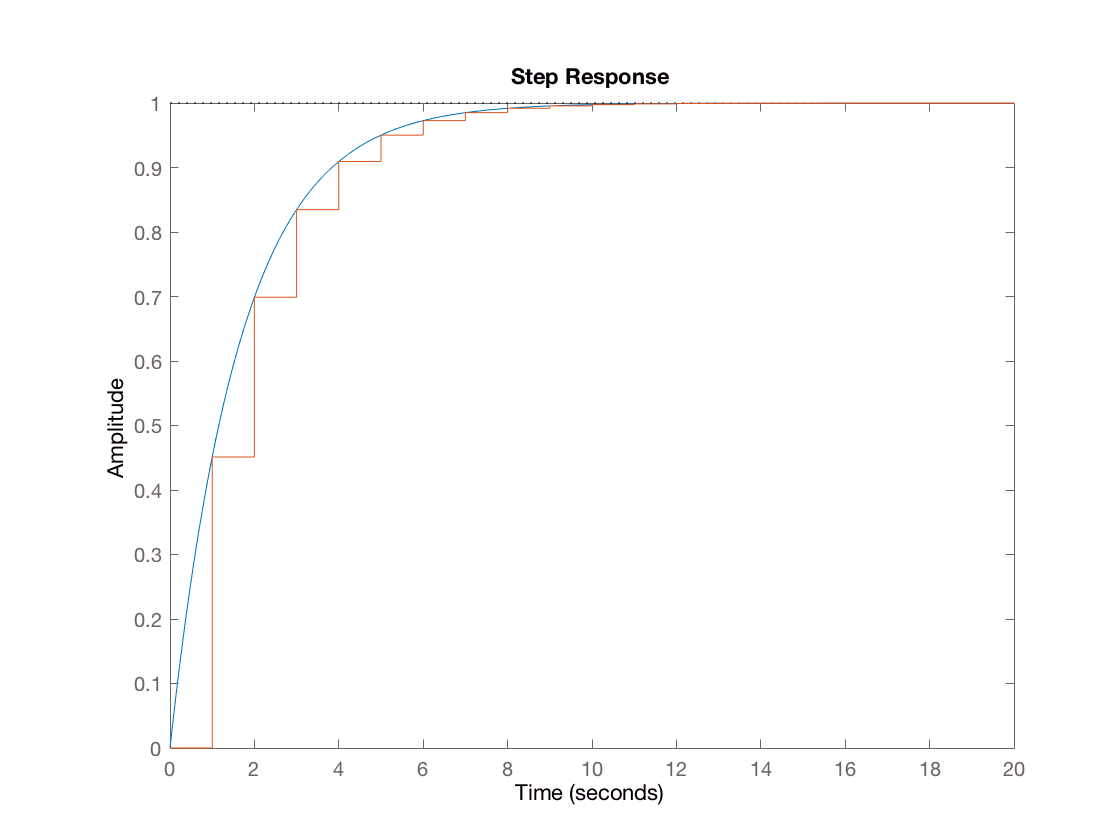

bfs = stepplot(Bf, Bfd);

À l'inverse du régulateur, les transmittances en boucles fermées sont identiques aux instants d'échantillonages. Nous remarquons en effet que tout comme dans la section précédente, les transmittances correspondent et concluons donc que les deux méthodes sont efficaces pour l'obtention de la transmittances discrète.